# Customer Satisfaction Survey

SampleSize=[12 28 52 112 248 502 1106 2400 5008]';
Dissatisfied=[3 4 10 21 43 83 195 431 970]';
Satisfied=SampleSize-Dissatisfied;

Compute the relative frequencies of the dissatisfied customers and satisfied customers in each sample

RelativeDissatisfied=Dissatisfied./SampleSize;
RelativeSatisfied=Satisfied./SampleSize;

Summarize the data and relative frequencies in a table.

Survey=table(SampleSize, Dissatisfied, Satisfied, RelativeDissatisfied, RelativeSatisfied)

Survey = 9×5 table
    SampleSize    Dissatisfied    Satisfied    RelativeDissatisfied    RelativeSatisfied
    __________    ____________    _________    ____________________    _________________

         12             3              9                0.25                   0.75     
         28             4             24             0.14286                0.85714     
         52            10             42             0.19231                0.80769     
        112            21             91              0.1875                 0.8125     
        248            43            205             0.17339                0.82661     
        502            83            419             0.16534                0.83466     
       1106           195            911             0.17631                0.82369     
       24

Determine if the releative frequencies appear to be approaching steady values.

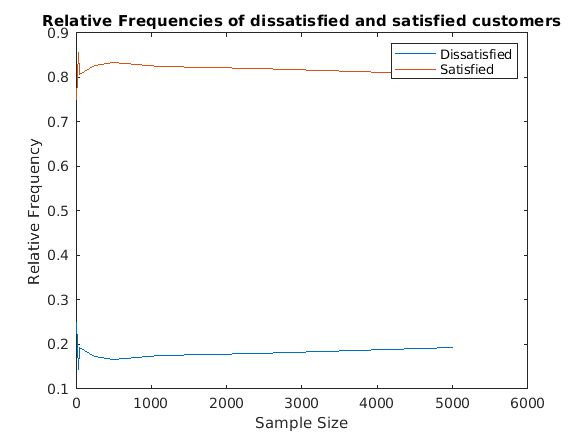

plot(Survey.SampleSize, Survey.RelativeDissatisfied, Survey.SampleSize, Survey.RelativeSatisfied)
title('Relative Frequencies of dissatisfied and satisfied customers')
xlabel('Sample Size')
ylabel('Relative Frequency')
legend('Dissatisfied','Satisfied')